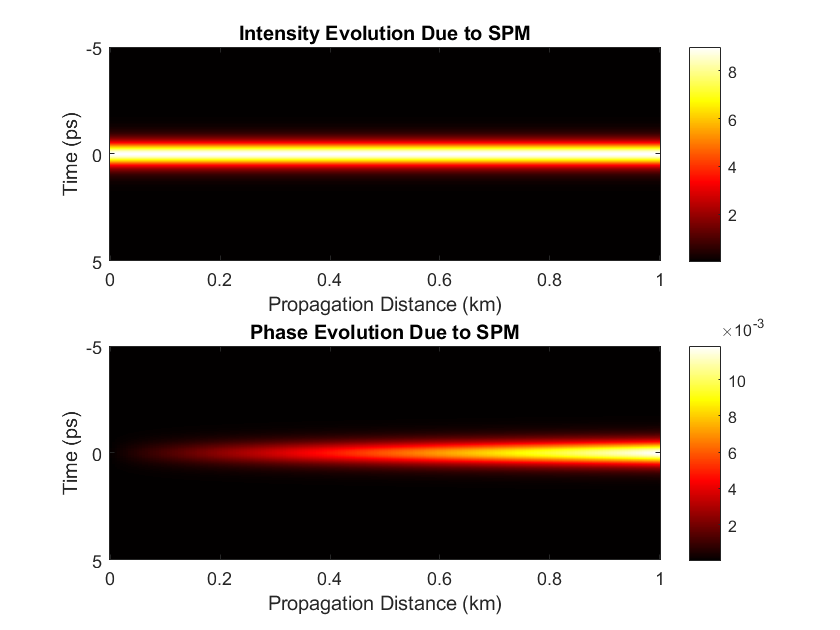

clc; clear; close all;

% Parameters
N = 1024;                 % Number of sample points
Tmax = 5;                 % Time window (ps)
t = linspace(-Tmax, Tmax, N); % Time axis (ps)

lambda = 1550e-9;         % Wavelength (m)
T0 = 0.5;                 % Initial pulse width (ps)
A0 = 3;                   % Peak amplitude (normalized)

L = 1;                    % Fiber length (km)
Nz = 200;                 % Number of steps in propagation

n2 = 2.6e-20;             % Nonlinear refractive index (m^2/W)
Aeff = 80e-12;            % Effective core area (m^2)
Gamma = (2*pi*n2) / (lambda*Aeff); % Nonlinear parameter (1/W/km)

A = A0 * sech(t/T0);      % Initial field amplitude

% Step size
dz = L / Nz;              % Step size in km

% Frequency axis
fs = 1 / (t(2) - t(1)); 
f = (-N/2:N/2-1) * (fs / N);
omega = 2 * pi * f;      % Angular frequency

% Initialize field and store evolution
A_z = A;
A_store = zeros(N, Nz);   % Store intensity over propagation
phase_store = zeros(N, Nz);

for n = 1:Nz
    % Nonlinear Phase Shift (SPM)
    phi_nl = Gamma * abs(A_z).^2 * dz;
    A_z = A_z .* exp(1j * phi_nl);
    
    % Store intensity and phase
    A_store(:,n) = abs(A_z).^2;
    phase_store(:,n) = unwrap(angle(A_z));
end

% Plot Results
figure;
subplot(2,1,1);
imagesc(linspace(0, L, Nz), t, A_store);
colormap jet; colorbar;
xlabel('Propagation Distance (km)'); ylabel('Time (ps)');
title('Intensity Evolution Due to SPM');

subplot(2,1,2);
imagesc(linspace(0, L, Nz), t, phase_store);
colormap hot; colorbar;
xlabel('Propagation Distance (km)'); ylabel('Time (ps)');
title('Phase Evolution Due to SPM');